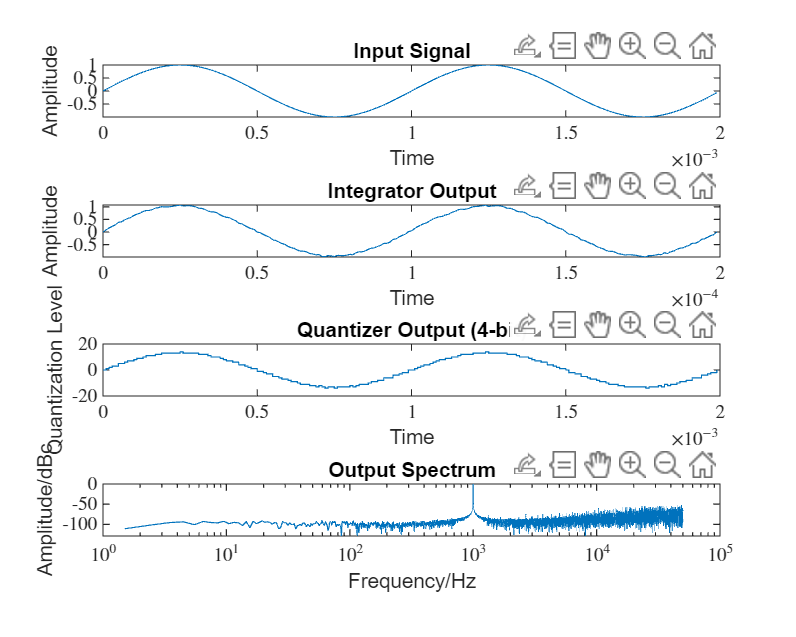

warning off
clear;
dt = 1e-6;
t = 0:dt:(1-dt);
signal = sin(2*pi*1e3*t) + 1e-3 * rand(1, length(t));
fs = 1e5;

[output_4bit, ax_4bit] = continuous_5bit_sigma_delta_adc(signal, dt, fs, 1.2, [1, 200]);

function [output, ax] = continuous_5bit_sigma_delta_adc(input, dt, fs, V_max, pr)
% input:          input signal with extreme short time interval (continuous)
% input_interval: time interval of input signal
% fs:             sampling rate
% V_max:          max voltage, the full range is ±V_max
% pr:             plot range, optional

% check necessity to plot
if nargin < 5
    do_plot = 0;
else
    do_plot = 1;
end

% time corresponding
t_in = 0:dt:(length(input)-1)*dt;
total_time = length(input) * dt;

dt_s = 1 / fs;
t_sa = 0:dt_s:total_time;

% Preallocation
integration = zeros(1, length(t_sa));
quantization = zeros(1, length(t_sa));
feedback = 0;

% quantizer level initializing
num_levels = 32;
level_width = 2 * V_max / num_levels; 

for n = 2:length(t_sa)-1
    t_start = t_sa(n);
    t_end = t_sa(n+1);
    
    % get the input signals in this sampling period
    input_section = input(t_in >= t_start & t_in < t_end);
    % integration and feedback
    integration(n) = integration(n-1) + (1/dt_s) * trapz(input_section - feedback)*dt;
    % quantization
    level = floor(integration(n) / level_width);
    level = mod(level + 16, num_levels) - 16;

    quantization(n) = level; % Store the quantized level
    feedback = level * level_width; % Update feedback based on the quantization level
end

output = quantization;

if do_plot
    ax = tiledlayout(5, 1);
    set(gcf, "position", [100, 25, 1000, 800])
    subplot(4, 1, 1);

    input_sampled = input(1:dt_s/dt:end);
    
    plot(t_sa(pr(1):pr(2)), input_sampled(pr(1):pr(2)));
    xlabel("Time");
    ylabel("Amplitude");
    title("Input Signal");
    ax_1 = gca;
    ax_1.TickLabelInterpreter = 'latex';

    subplot(4, 1, 2);
    plot(t_in(pr(1):pr(2)), integration(pr(1):pr(2)));
    xlabel("Time");
    ylabel("Amplitude");
    title("Integrator Output");
    ax_2 = gca;
    ax_2.TickLabelInterpreter = 'latex';

    subplot(4, 1, 3);
    stairs(t_sa(pr(1):pr(2)), quantization(pr(1):pr(2)));
    xlabel("Time");
    ylabel("Quantization Level");
    title("Quantizer Output (4-bit)");    
    ax_3 = gca;
    ax_3.TickLabelInterpreter = 'latex';

    N_q = length(output);
    F_q = fftshift(fft(output)); % Calculate the FFT and shift
    f = linspace(-fs/2, fs/2 - fs/N_q, N_q);

    subplot(4, 1, 4);
    spectrum = 20*(log(abs(F_q) / max(abs(F_q))) / log(10));
    plot(f(f>=1), spectrum(f>=1)); 
    set(gca, "xscale", "log");
    xlabel("Frequency/Hz");
    ylabel("Amplitude/dBc");
    title("Output Spectrum");
    ax_4 = gca;
    ax_4.TickLabelInterpreter = 'latex';
end
end

% --------------------------------------------------

function output = phase_detector(sig1, sig2)
multi = sig1 .* sig2;

freq_spec = fft(multi);
idx = find(freq_spec >= 0.1);

[b, a] = butter(3, mean(idx), "high");
output = filter(b, a, multi);
end

% --------------------------------------------------

function output = freq_detector(sig1, sig2, fs)

    multi = sig1 .* sig2;

    freq_spec = fft(multi);
    freq_mag = abs(freq_spec); 

    freq_mag(1) = 0; 
    [~, idx] = max(freq_mag); 

    n = length(multi);
    freqs = (0:n-1) * (fs / n); 
    output = freqs(idx); 

end
